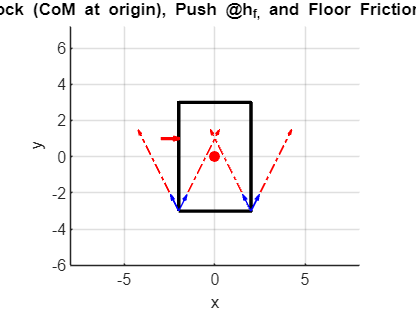

% Modern Robotics Chapter 12.1.2 Rolling, Sliding, and Breaking

clc; clear; close all;

% For the following problem:
width = 4;
height = 6;
h_f = 1; % height of finger above CoM
fric = 0.5;
mass = 1;
draw_rect(width, height, h_f, fric);
hold on;


push_acc = 6; % Same as gravity for now

% With the bottom RIGHT contact labeled B
% The bottom LEFT contact labeled C


% Let's also quickly do the basic scalar check from my analysis:
% Sliding occurs when F >= mu*m*g
% Tipping occurs when F*hf > mg*rw

% So let's see which is true!
syms mu m g hf r_w a_p

sliding_check = m*a_p*mu >= mu*m*g

$$sliding\_check = g\,m\,\mu \leq a_{p}\,m\,\mu$$

tipping_check = m*a_p*hf > m*g*r_w

$$tipping\_check = g\,m\,r_{w}<a_{p}\,\mathrm{hf}\,m$$


slide = subs(sliding_check, [mu g m], [fric 9.8 mass])

$$slide = \frac{49}{10}\leq \frac{a_{p}}{2}$$

tip = subs(tipping_check, [mu g m r_w hf], [fric 9.8 mass width/2 h_f])

$$tip = \frac{98}{5}<a_{p}$$


slide = subs(slide, a_p, push_acc);
tip = subs(tip, a_p, push_acc);

if slide && tip
    disp('Slide and Tip!')
elseif tip && ~slide
    disp('Tip Only!')
elseif slide && ~tip
    disp('Slide Only!')
else
    disp('Neither tip nor slide!')
end

Neither tip nor slide!


clear F mu m g hf r_w

## We need to now analyze the following three cases:

% 1. The payload slides to the right
% 2. The payload rolls about the bottom right
% 3. The payload slides and rolls about the bottom right


## And then apply the corresponding contacts and contact modes to the rigid body dynamics equation:


$$F_{ext} + \sum{k_i F_i} =0$$


NOTE: Origin is at the CoM

## First, Let's Treat F5 (the finger) as an unknown force (k5F5)

syms a_p hf real
syms m g mu W H positive

% F_g is force of gravity directly downwards, no moment generated
F_ext = [0;0;-m*g];

% Now find contact wrenches (2 at B&C, 1 at finger D), each wrench has unit force=1
% The GENERALIZED L&R sliding (+ or - respectively) of form (fx fy fz)':
f13 = (1/(sqrt(mu.^2 +1)))*[mu; 1; 0];
f24 = (1/(sqrt(mu.^2 +1)))*[-mu; 1; 0]; % (for full geometric analysis, see notability)
f5 = [1; 0; 0];

% Distance from CoM to each contact point (1,2 and 3,4 share the same point)
p12 = [W/2; -H/2; 0];
p34 = [-W/2; -H/2; 0];
p5 = [-W/2; h_f; 0];

f1_skew = skew(p12)*f13;
F1 = [f1_skew(3); f13(1:2)];

f2_skew = skew(p12)*f24;
F2 = [f2_skew(3); f24(1:2)];

f3_skew = skew(p34)*f13;
F3 = [f3_skew(3); f13(1:2)];

f4_skew = skew(p34)*f24;
F4 = [f4_skew(3); f24(1:2)];

f5_skew = skew(p5)*f5;
F5 = [f5_skew(3); f5(1:2)];

% F_i matrix
F_i = [F1 F2 F3 F4 F5];

% Finally, the full Quasistatic EoM for rigid body
syms k1 k2 k3 k4 k5 real
k_i = [k1; k2; k3; k4; k5];
eqn = F_ext + F_i*k_i == 0;

% And with substituted nominal values for gravity, friction, and mass
% eqn = subs(eqn, [g mu m W H hf], [9.8 fric mass, width, height, h_f]);


## Case 1: Sliding to the Right

% Here, point B & C have left friction only along left cone edge
fprintf('\n\n Case 1: Sliding to the Right (k1 = k3 = 0)')



 Case 1: Sliding to the Right (k1 = k3 = 0)


% Eqn now looks like Ax = B where B is F_ext and we want x (k_i)
Fi = F_i(:,[2, 4, 5]);
ki = subs(linsolve(Fi, -F_ext), [mu, W, H], [fric, width, height]);
k_i == [0 ki(1) 0 ki(2) ki(3)]'

$$ans = \left(\begin{array}{c} k_{1}=0\\ k_{2}=\frac{\sqrt{5}\,g\,m}{2}\\ k_{3}=0\\ k_{4}=0\\ k_{5}=\frac{g\,m}{2} \end{array}\right)$$

## Case 2: Tipping over Right Edge

% Here, point C breaks contact, point B has Roll constraint
fprintf('\n\n Case 2: Tipping to the Right (k3 = k4 = 0)')



 Case 2: Tipping to the Right (k3 = k4 = 0)


Fi = subs(F_i(:,[1, 2, 5]));
ki = subs(linsolve(Fi, -F_ext), [mu W H], [fric width height]);
k_i == [ki(1) ki(2) 0 0 ki(3)]'

$$ans = \left(\begin{array}{c} k_{1}=0\\ k_{2}=\frac{\sqrt{5}\,g\,m}{2}\\ k_{3}=0\\ k_{4}=0\\ k_{5}=\frac{g\,m}{2} \end{array}\right)$$

## Case 3: Tipping and Sliding

% Here, point C breaks, point B has only left slide
fprintf('\n\n Case 3: Tipping AND Sliding (k1 = k3 = k4 = 0)')



 Case 3: Tipping AND Sliding (k1 = k3 = k4 = 0)


Fi = subs(F_i(:,[2, 5]));
ki = subs(linsolve(Fi, -F_ext), [mu W H], [fric width height]);

k_i == [0 ki(1) 0 0 ki(2)]'

$$ans = \left(\begin{array}{c} k_{1}=0\\ k_{2}=\infty \\ k_{3}=0\\ k_{4}=0\\ k_{5}=\infty \end{array}\right)$$

## Case 4: Sticking to the Surface

% Here, we assume full contact and full Roll-Roll constraint is active 
% THIS ONLY OCCURS IF NONE OF THE OTHER MODES ARE ACTIVE
% (recall Roll constraint == sticking)

% Solve for ki
% sol_stick = solve(eqn, [k1 k2 k3 k4])
% ki = [sol_stick.k1, sol_stick.k2, sol_stick.k3, sol_stick.k4] >= 0
% 
% % Enforce the condition k_i >= 0 to find valid wrenches
% F_valid_var = solve(ki, a_p, 'ReturnConditions',true)
% 
% fprintf('a_push is valid under the constraints (variables): \n%s\n', F_valid_var.conditions)


## NOW LET'S TREAT FINGER AS CONTROL INPUT

F_i = [F1 F2 F3 F4]

$$F\_i = \left(\begin{array}{cccc} \frac{W}{2\,\sqrt{\mu^{2}+1}}+\frac{H\,\mu }{2\,\sqrt{\mu^{2}+1}} & \frac{W}{2\,\sqrt{\mu^{2}+1}}-\frac{H\,\mu }{2\,\sqrt{\mu^{2}+1}} & \frac{H\,\mu }{2\,\sqrt{\mu^{2}+1}}-\frac{W}{2\,\sqrt{\mu^{2}+1}} & -\frac{W}{2\,\sqrt{\mu^{2}+1}}-\frac{H\,\mu }{2\,\sqrt{\mu^{2}+1}}\\ \frac{\mu }{\sqrt{\mu^{2}+1}} & -\frac{\mu }{\sqrt{\mu^{2}+1}} & \frac{\mu }{\sqrt{\mu^{2}+1}} & -\frac{\mu }{\sqrt{\mu^{2}+1}}\\ \frac{1}{\sqrt{\mu^{2}+1}} & \frac{1}{\sqrt{\mu^{2}+1}} & \frac{1}{\sqrt{\mu^{2}+1}} & \frac{1}{\sqrt{\mu^{2}+1}} \end{array}\right)$$

k_i = [k1; k2; k3; k4]

$$k\_i = \left(\begin{array}{c} k_{1}\\ k_{2}\\ k_{3}\\ k_{4} \end{array}\right)$$


% Fp is force of pushing
syms a_p F real
fp = [F;0;0];               % 3D linear (x,y,z) force
fp_skew = skew([-W/2; hf; 0])*fp;       % Angular (about z) wrench component
Fp = [fp_skew(3); fp(1:2)]         % Total Wrench

$$Fp = \left(\begin{array}{c} -F\,\mathrm{hf}\\ F\\ 0 \end{array}\right)$$


% General Equation
eqn = F_ext + F_i*k_i == Fp;

% subs(eqn, [mu W H g m hf], [fric width height 9.8 mass h_f])

## Case 1: Sliding to the Right

% Here, point B & C have left friction only along left cone edge
fprintf('\n\n Case 1: Sliding to the Right (k1 = k3 = 0)')



 Case 1: Sliding to the Right (k1 = k3 = 0)


% % Eqn now looks like Ax = B where A is F_i, B is F_push-F_ext, and we want x (k_i)
% Fi = [F2 F4];
% ki = subs(linsolve(Fi, Fp-F_ext), [mu W H], [fric width height]);
% k_i == [0 ki(1) 0 ki(2)]'

% Solve for Ki
Fi = [F2 F4];
ki = [k2; k4];

eqn = F_ext + Fi*ki == Fp;
eqn = subs(eqn, [mu W H g m hf], [fric width height 9.8 mass h_f]);
sol_slide = solve(eqn)

sol_slide = struct with fields:
     F: -49/10
    k2: (49*5^(1/2))/10
    k4: 0




% Enforce the condition k_i >= 0 to find valid wrenches
F_valid_num = solve([sol_slide.k2 sol_slide.k4]>=0, F, 'ReturnConditions',true);

fprintf('a_push is valid under the constraints (numerical): \n%s\n', F_valid_num.conditions)

a_push is valid under the constraints (numerical): 
in(x, 'real')


## Case 2: Tipping over Right Edge

% Here, point C breaks contact, point B has Roll constraint
fprintf('\n\n Case 2: Tipping to the Right (k3 = k4 = 0)')



 Case 2: Tipping to the Right (k3 = k4 = 0)


% Fi = [F1 F2];
% ki = subs(linsolve(Fi, Fp-F_ext), [mu W H], [fric width height]);
% k_i == [ki(1) ki(2) 0 0]'

% % Solve for Ki
Fi = [F1 F2];
ki = [k1; k2];

eqn = F_ext + Fi*ki == Fp;
eqn = subs(eqn, [mu W H g m hf], [fric width height 9.8 mass h_f]);
sol_tip = solve(eqn)

sol_tip = struct with fields:
     F: -49/10
    k1: 0
    k2: (49*5^(1/2))/10



% eq = subs(eqn, [k3 k4], [0 0])
% solve(eq)
% 
% sol_tip = solve(eqn);
% ki = [sol_tip.k1, sol_tip.k2] >= 0
% ki = subs(ki, [k3 k4], [0 0])
% 
% % Enforce the condition k_i >= 0 to find valid wrenches
% F_valid_num2 = solve(ki, a_p, 'ReturnConditions',true);
% 
% fprintf('a_push is valid under the constraints (numerical): \n%s\n', F_valid_num2.conditions)


## Case 3: Tipping and Sliding

% Here, point C breaks, point B has only left slide
fprintf('\n\n Case 3: Tipping AND Sliding (k1 = k3 = k4 = 0)')



 Case 3: Tipping AND Sliding (k1 = k3 = k4 = 0)


Fi = subs(F_i(:,[2, 5]))

Index in position 2 exceeds array bounds. Index must not exceed 4.

Error in indexing (line 968)
            R_tilde = builtin('subsref',L_tilde,Idx);

ki = subs(linsolve(Fi, -F_ext), [mu W H], [fric width height]);
k_i == [0 ki(1) 0 0 ki(2)]'

% % Solve for Ki
% sol_tip_slide = solve(eqn);
% ki = [sol_tip_slide.k1] >= 0
% ki = subs(ki, [k2 k3 k4], [0 0 0])
% 
% % Enforce the condition k_i >= 0 to find valid wrenches
% F_valid_num3 = solve(ki, a_p, 'ReturnConditions',true);
% 
% fprintf('a_push is valid under the constraints (numerical): \n%s\n', F_valid_num3.conditions)



## Case 4: Sticking to the Surface

% Here, we assume full contact and full Roll-Roll constraint is active 
% THIS ONLY OCCURS IF NONE OF THE OTHER MODES ARE ACTIVE
% (recall Roll constraint == sticking)

% Solve for ki
% sol_stick = solve(eqn, [k1 k2 k3 k4])
% ki = [sol_stick.k1, sol_stick.k2, sol_stick.k3, sol_stick.k4] >= 0
% 
% % Enforce the condition k_i >= 0 to find valid wrenches
% F_valid_var = solve(ki, a_p, 'ReturnConditions',true)
% 
% fprintf('a_push is valid under the constraints (variables): \n%s\n', F_valid_var.conditions)


% Case 0 full sticking
fprintf('\n\nCase 0 full sticking')
[ok, sol, cond] = testContactMode(eqn, [1 2 3 4]);
testMode(sol, cond)


fprintf('\n\nCase 1 sliding to the right')
% Case 1 sliding
[ok, sol, cond] = testContactMode(eqn, [1 3]);
testMode(sol, cond)


fprintf('\n\nCase 2 tipping about right edge')
% Case 2 rolling
[ok, sol, cond] = testContactMode(eqn, [1 2]);
testMode(sol, cond)


fprintf('\n\nCase 3 tipping + sliding')
% Case 3 slide+roll
[ok, sol, cond] = testContactMode(eqn, [1 2]);
testMode(sol, cond)

## Temp plotting arrows for verification

qx = 49/10;
qy = -mass*9.8;
quiver(0,h_f, qx, qy)

temp = subs(F1, [W H mu], [width height fric]);
quiver(width/2,-height/2, temp(2), temp(3))

temp2 = subs(F1R, [W H mu], [width height fric]);
quiver(width/2,-height/2, temp2(2), temp2(3))

temp3 = subs(F2L, [W H mu], [width height fric]);
quiver(-width/2,-height/2, temp3(2), temp3(3))

temp4 = subs(F2R, [W H mu], [width height fric]);
quiver(-width/2,-height/2, temp4(2), temp4(3))

## Functions

function testMode(sol, cond)
try
    F_cond = sol.F_push >= 0;
    k_cond = all([sol.k1, sol.k2] >= 0);
    if ~F_cond || ~k_cond
        fprintf('infeasible!')
        sol
    else
        fprintf('FEASIBLE!')
    end
catch
    fprintf('infeasible!')
    sol
end

end

function [feasible, sol, conds] = testContactMode(EoM_sub, activeContacts)
% TESTCONTACTMODE Test one contact mode symbolically
%   [feasible, sol, conds] = testContactMode(EoM_sub, activeContacts)
%   EoM_sub         : 3x1 symbolic equilibrium equations (already subs g, mu, m)
%   activeContacts : vector of indices (subset of 1:4) of active contacts
%
%   Outputs:
%     feasible : true if a symbolic solution satisfying all eqns and inequalities exists
%     sol      : struct with fields .F_push and .k# for each active contact
%     conds    : symbolic condition under which the solution is valid (false if infeasible)

  % Define symbolic variables
  syms F_push k1 k2 k3 k4 real
  ki = [k1, k2, k3, k4];

  % Zero out inactive contacts in the equilibrium equations
  inactive = setdiff(1:4, activeContacts);
  eqs = EoM_sub;
  for idx = inactive
    eqs = subs(eqs, ki(idx), 0);
  end

  % Define the unknowns: push force and the active contact ki's
  vars = [F_push, ki(activeContacts)];

  % Solve symbolically with conditions
  S = solve(eqs, vars, 'ReturnConditions', true);
  conds = S.conditions;

  % Determine feasibility
  feasible = ~isequal(conds, false);

  % Pack solutions into struct
  sol = struct();
  if feasible
    sol.F_push = S.F_push;
    for j = 1:numel(activeContacts)
      name = sprintf('k%d', activeContacts(j));
      sol.(name) = S.(name);
    end
  end
end


function S = skew(v)
    S = [0 -v(3) v(2);
        v(3) 0 -v(1);
        -v(2) v(1) 0];
end

function draw_rect(width, height, hf, mu)
    % Derived
    w = width;  h = height;
    phi    = atan(mu);           % friction‐cone half–angle
    Lfc    = 1;              % length of friction‐cone arrows
    
    % Rectangle corners (closed loop)
    xRect = [-w/2,  w/2,  w/2, -w/2, -w/2];
    yRect = [-h/2, -h/2,  h/2,  h/2, -h/2];
    
    figure; hold on;
    % 1) Block
    plot(xRect, yRect, 'k-', 'LineWidth', 2);
    
    % 2) CoM at origin
    plot(0,0,'ro','MarkerFaceColor','r','MarkerSize',6);
    
    % 3) Push arrow (from left face at height hf)
    x0 = -w/2;  y0 = hf;
    quiver(x0-1, y0, 1, 0, 0, 'r', 'LineWidth', 2, 'AutoScale','off', 'MaxHeadSize',10);
    
    % 4) Friction‐cone rays at the two bottom contacts
    contacts = [-w/2, -h/2;   % left bottom
                 w/2, -h/2];  % right bottom
    
    % Cone edge directions: normal=(0,1) rotated by ±phi
    d1 = [ sin(phi),  cos(phi) ];
    d2 = [-sin(phi),  cos(phi) ];
    
    for i=1:2
        xi = contacts(i,1);
        yi = contacts(i,2);
        quiver(xi, yi, d1(1)*5, d1(2)*5, 0, 'r-.', 'LineWidth',1);
        quiver(xi, yi, d1(1)*Lfc, d1(2)*Lfc, 0, 'b', 'LineWidth',1, 'AutoScale','off', 'MaxHeadSize',4);
        quiver(xi, yi, d2(1)*5, d2(2)*5, 0, 'r-.', 'LineWidth',1);
        quiver(xi, yi, d2(1)*Lfc, d2(2)*Lfc, 0, 'b', 'LineWidth',1, 'AutoScale','off', 'MaxHeadSize',4);
    end
    
    % Formatting
    axis equal;
    grid on;
    xlabel('x');
    ylabel('y');
    title('2D Block (CoM at origin), Push @h_f, and Floor Friction Cones');
    xlim([-2*w, 2*w]);
    ylim([-h, h*1.2]);
    hold off;
end
